# Deep Learning Network for Image Classification

Create Simple Deep Learning Network for Image Classification; in particular we create and use

a Convolutional Neural Network (CNN) using Matlab commands.

% Example from Help Center Matlab
% https://www.mathworks.com/help/deeplearning/ug/create-simple-deep-learning-network-for-classification.html

% This example shows how to create and train a simple convolutional neural network 
% for deep learning classification (image recognition)
% 
% The example demonstrates how to:
% 
% 1) Load and explore image data.
% 2) Define the network architecture.
% 3) Specify training options.
% 4) Train the network.
% 5) Predict the labels of new data and calculate the classification accuracy.

clc
clear


#### 1) Load Image Data Store

Load the digit sample data as an image datastore. imageDatastore automatically labels the images based on folder names and stores the data as an ImageDatastore object. An image datastore enables you to store large image data.

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');


#### 2) Explore Image Data

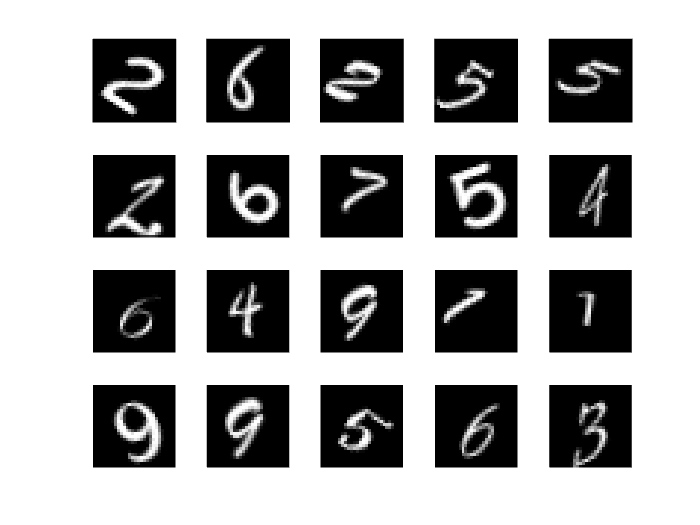

% Display some of the images in the datastore
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

% size of input
figure;
img = readimage(imds,1);
size(img)

ans =     28    28


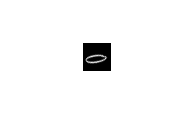

imshow(img)

% classes of output
labelCount = countEachLabel(imds)

labelCount = 10×2 table
    Label    Count
    _____    _____

      0      1000 
      1      1000 
      2      1000 
      3      1000 
      4      1000 
      5      1000 
      6      1000 
      7      1000 
      8      1000 
      9      1000 


#### 3) Split Data: Divide the data into training and validation data sets.

% 3) Data Split

% Each category in the training set contains 750 images, 
% Validation set contains the remaining images from each label. 
% splitEachLabel splits the datastore digitData into two new datastores, 
% trainDigitData and valDigitData.

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

% classes of imdsTrain
countEachLabel(imdsTrain)

ans = 10×2 table
    Label    Count
    _____    _____

      0       750 
      1       750 
      2       750 
      3       750 
      4       750 
      5       750 
      6       750 
      7       750 
      8       750 
      9       750 


% classes of imdsValidation
countEachLabel(imdsValidation)

ans = 10×2 table
    Label    Count
    _____    _____

      0       250 
      1       250 
      2       250 
      3       250 
      4       250 
      5       250 
      6       250 
      7       250 
      8       250 
      9       250 


#### 4) Define Network Architecture

We define a convolutional neural network.

layers = [
    % L1: INPUT LAYER
    imageInputLayer([28 28 1])
    % imageInputLayer is where you specify the image size;
    % in this case, is 28-by-28-by-1. 
    % These numbers correspond to the height, width, and the channel size. 
    % grayscale images -> channel size (color channel) is 1. 
    % color image -> channel size is 3, corresponding to the RGB values.
    
    % L2~4: CONVOLUTION + Normalization + ReLU
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    %  the first argument is filterSize, which is the height and width of the filters 
    %  the training function uses while scanning along the images. 
    % In this example, the number 3 indicates that the filter size is 3-by-3. 
    % Use the 'Padding' name-value pair to add padding to the input feature map.
    % See next link for 'filter', 'padding', "stride'
    % https://medium.com/swlh/convolutional-neural-networks-part-2-padding-and-strided-convolutions-c63c25026eaa
    
    % L5: MAX POOLING LAYER
    maxPooling2dLayer(2,'Stride',2)
    % Convolutional layers (with activation functions) are sometimes followed by 
    % a down-sampling operation that reduces the spatial size of the feature map
    % and removes redundant spatial information.
    % max pooling layer returns the maximum values of rectangular regions of inputs: 
    % the size of the rectangular region is [2,2]. 
    % 'Stride' specifies the step size of scanning along the input.
    
    % L6~8: CONVOLUTION + Normalization + ReLU
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    % L9: MAX POOLING LAYER
    maxPooling2dLayer(2,'Stride',2)
    
    % L10~12: CONVOLUTION + Normalization + ReLU
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    % L13: CONNECTED LAYER
    fullyConnectedLayer(10)
    % the fully connected layer has neurons connected to all neurons in the preceding layer. 
    % This layer combines all the learned features to identify the larger patterns. 
    % and to classify the images. 
    % OutputSize is equal to the number of classes in the target data. 
    % Here, the output size is 10, corresponding to the 10 classes. 
    
    % L14: SOFTMAX LAYER
    softmaxLayer
    % softmax activation function normalizes the output of the fully connected layer. 
    % The output of the softmax layer consists of positive numbers that sum to one, 
    % which can then be used as classification probabilities by the classification layer.
    
    % L15: CLASSIFICATION LAYER
    classificationLayer];
    % The final layer is the classification layer. 
    % It uses the probabilities returned by the softmax activation function 
    % to assign the input to one of the mutually exclusive classes and compute the loss. 
    

#### 5) Analyze Network

% analyze the network at a glance
analyzeNetwork(layers)

#### 6) Specify training options.

Train the network using stochastic gradient descent with momentum (SGDM) 

with an initial learning rate of 0.01. Set the maximum number of epochs to 4. 

An epoch is a full training cycle on the entire training data set. 

Monitor the network accuracy during training by specifying validation data and validation frequency. 

Shuffle the data every epoch. 

The software trains the network on the training data and calculates the accuracy on the validation data at regular intervals during training. 

The validation data is not used to update the network weights. 

Turn on the training progress plot, and turn off the command window output.

% options for trainig
options = trainingOptions('sgdm', ...  % stocastic gradient descend with momentum
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'MiniBatchSize',50, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

% % options for trainig
% options = trainingOptions('adam', ...  % stocastic gradient descend with momentum
%     'InitialLearnRate',0.01, ...
%     'MaxEpochs',4, ...
%     'MiniBatchSize',50, ...
%     'Shuffle','every-epoch', ...
%     'ValidationData',imdsValidation, ...
%     'ValidationFrequency',30, ...
%     'Verbose',false, ...
%     'Plots','training-progress');

% % options for trainig
% options = trainingOptions('rmsprop', ...  % stocastic gradient descend with momentum
%     'InitialLearnRate',0.01, ...
%     'MaxEpochs',4, ...
%     'MiniBatchSize',50, ...
%     'Shuffle','every-epoch', ...
%     'ValidationData',imdsValidation, ...
%     'ValidationFrequency',30, ...
%     'Verbose',false, ...
%     'Plots','training-progress');

#### 7) Train the network.

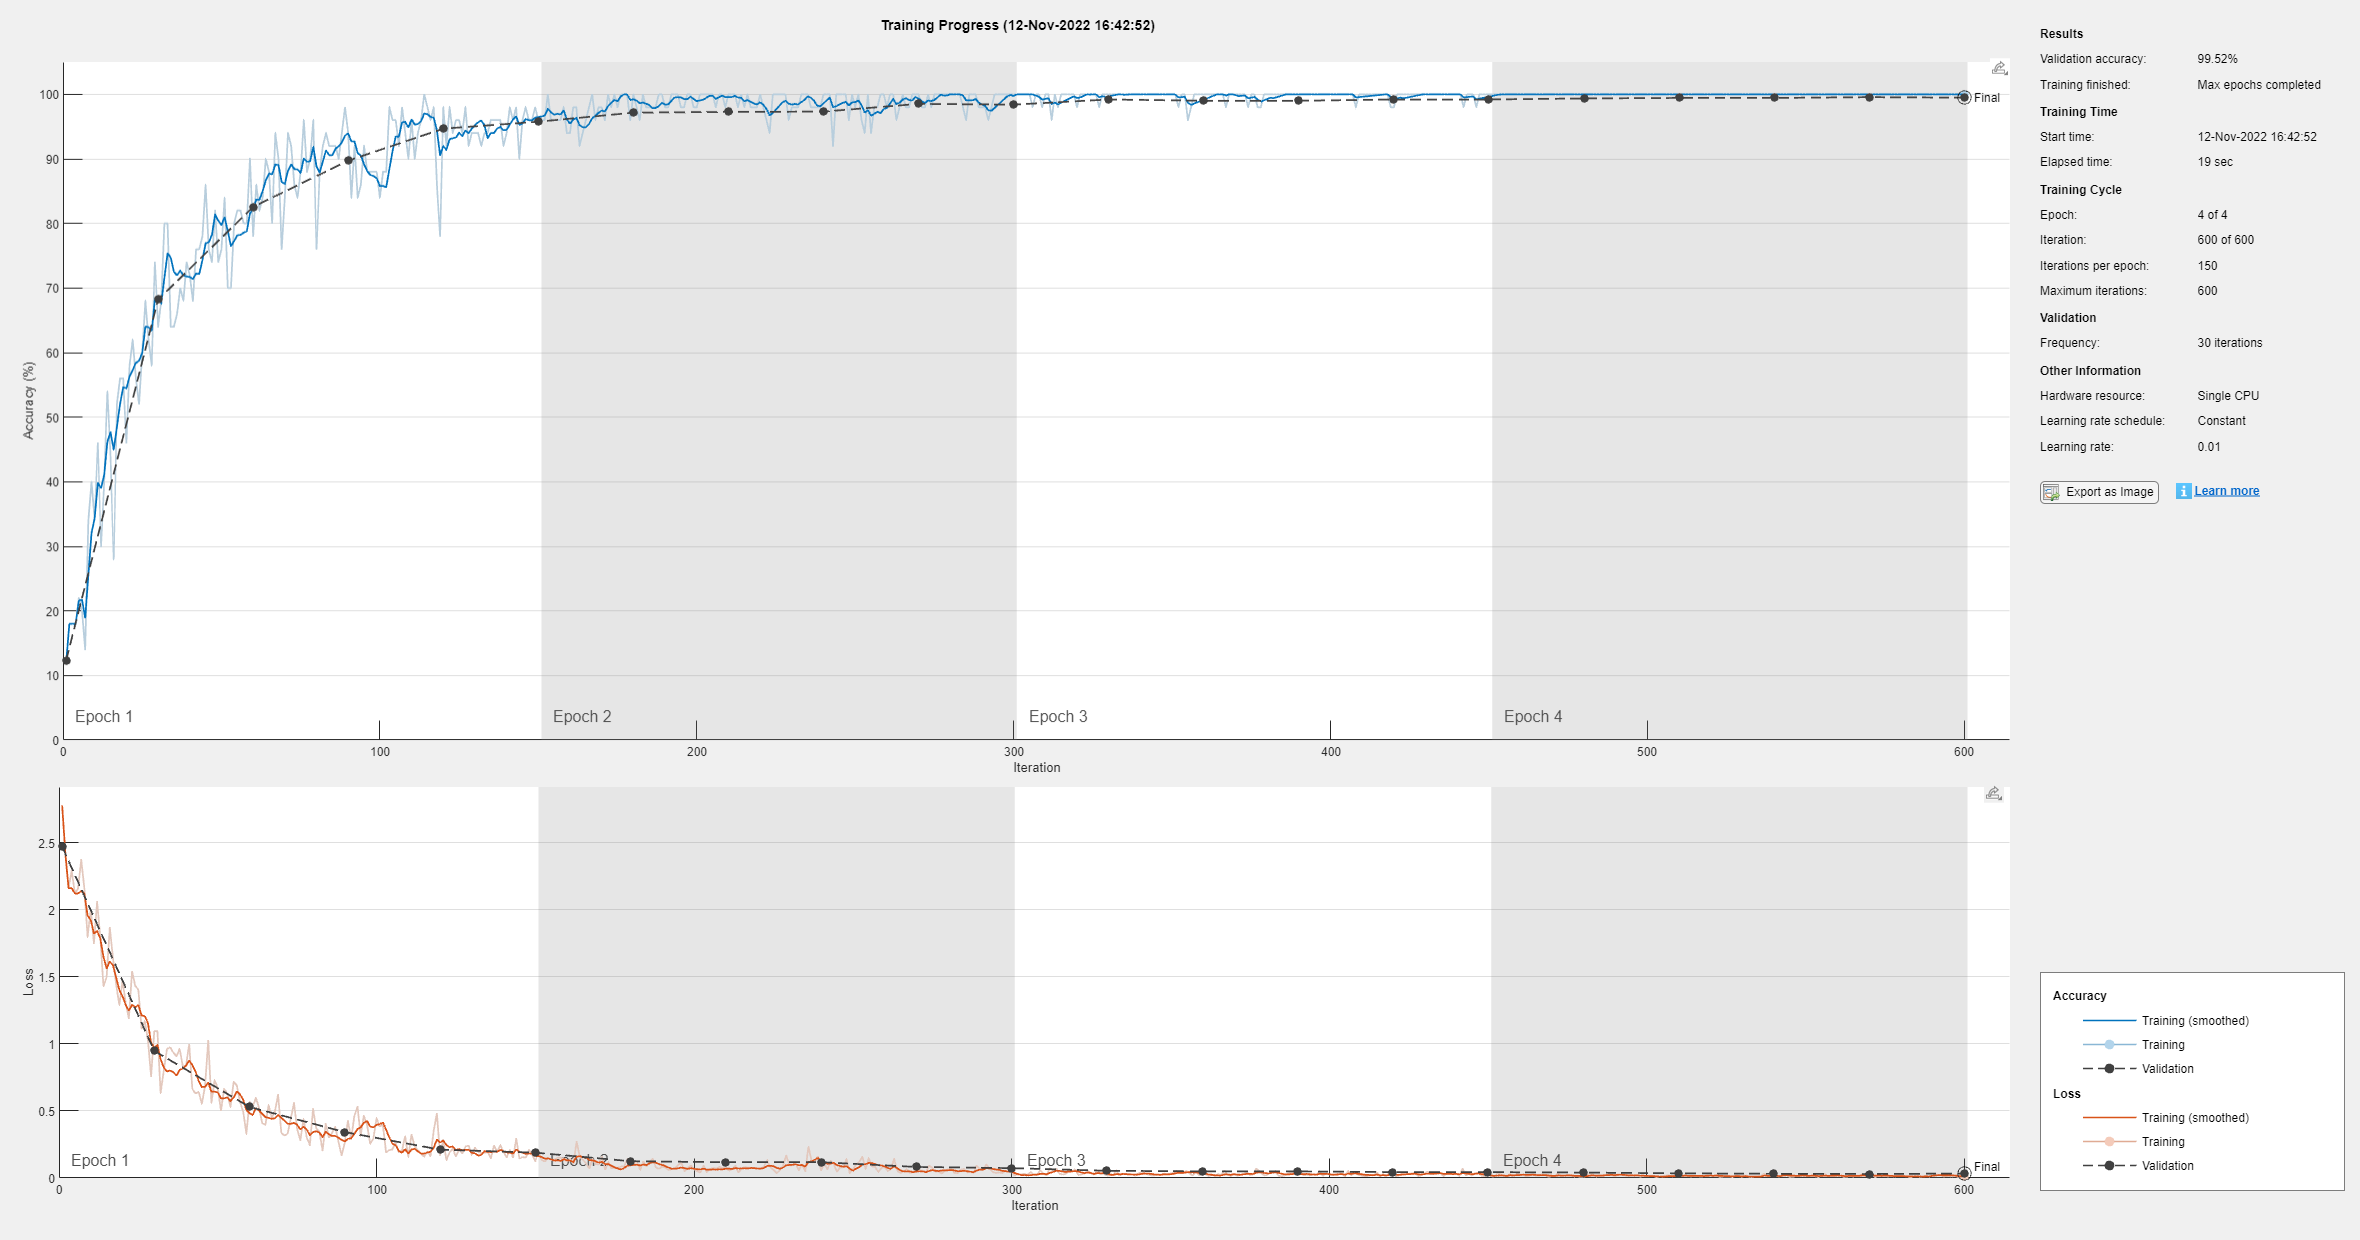

net = trainNetwork(imdsTrain,layers,options);

net.Layers(2) % layer 2 = convolutional2d

ans =   Convolution2DLayer with properties:

              Name: 'conv_1'

   Hyperparameters
        FilterSize: [3 3]
       NumChannels: 1
        NumFilters: 8
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'same'
       PaddingSize: [1 1 1 1]
      PaddingValue: 0

   Learnable Parameters
           Weights: [3×3×1×8 single]
              Bias: [1×1×8 single]

  Show all properties


act1 = activations(net,img,'conv_1');

% query size
sz = size(act1)

sz =     28    28     8


% reshape the 3-D array to a 4-D array
act1 = reshape(act1,[sz(1) sz(2) 1 sz(3)]);
szact = size(act1)

szact =     28    28     1     8


imshow(img)

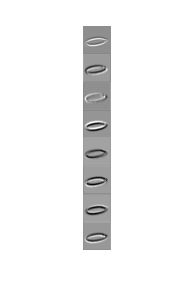

% show filters
I = imtile(mat2gray(act1),'GridSize',[8 1]);
imshow(I)

#### 8) Predict the labels of new data and calculate the classification accuracy.

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9952

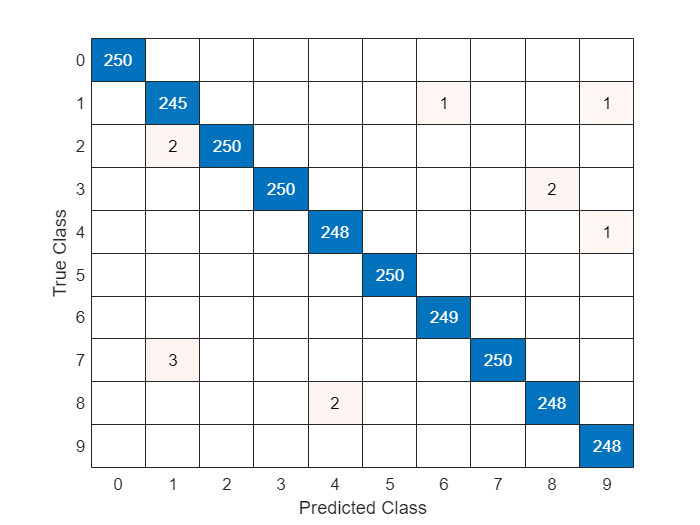

% plot confusion matrix
figure
confusionchart(YPred,YValidation)